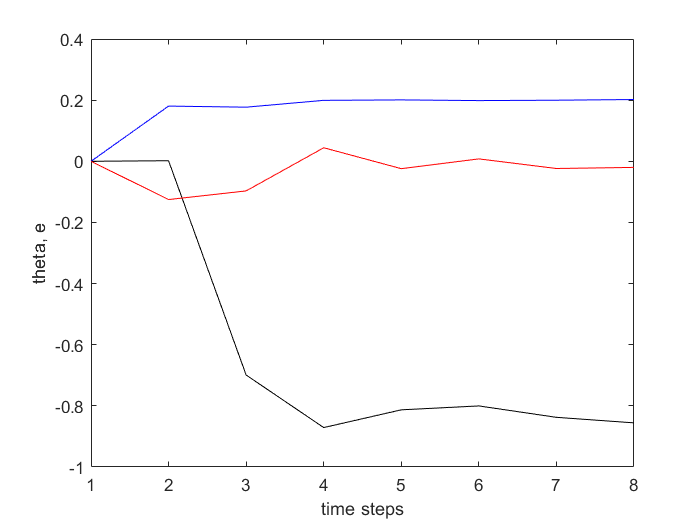

% Basic recursive least squares method
% N - number of identification steps
% c - covariance matrix
% d - regression vector
% theta - vector of the parameter estimates
% ep(k)- prediction error
% eps - auxiliary parameter
% y(k) - process output
% u(k) - controller output
% input variables
u=[-0.6918 0.858 1.254 -1.5937 -1.441 0.5711 -0.3999 0.69];
% output variables
y=[0.0071 -0.1252 0.0583 0.307 -0.0744 -0.342 -0.1839 -0.2539];
N=8;
theta= [0 0]'; % initial vector of parameter estimates
c = 1000*eye(2); % initial covariance matrix
for k=2:1:N
    d = [ -y(k-1) u(k-1) ]'; % new data vector
    ep(k)= y(k)-theta'*d;
    eps = d'*c*d;
    theta = theta + (c*d*ep(k)) / (1+eps); % theta update
    c = c-(c*d*d'*c)/(1+eps); % new covariance matrix
    a1(k)=theta(1);
    b1(k)=theta(2);
end
figure;
plot(a1,'k');
hold on;
plot(b1,'b');
plot(ep,'r');
xlabel('time steps')
ylabel('theta, e')

a1

a1 =          0    0.0019   -0.6991   -0.8710   -0.8130   -0.8002   -0.8375   -0.8556


b1

b1 =          0    0.1806    0.1770    0.1993    0.2008    0.1985    0.1998    0.2020
